# Obstacle-Free Path Planning Using Hybrid A Star

Plan a collision-free path for a vehicle through a parking lot by using the Hybrid A* algorithm.

## Create and Assign Map to State Validator

Load the cost values of cells in the vehicle costmap of a parking lot.

load parkingLotCostVal.mat % costVal

Create a [binaryOccupancyMap](docid:nav_ref#bunq527) with cost values.

map = binaryOccupancyMap(costVal);

Create a `stateValidator` object for collision checking.

validator = validatorOccupancyMap;

Assign the map to the `stateValidator` object.

validator.Map = map;

## Plan and Visualize Path

Initialize the [plannerHybridAStar](docid:nav_ref#object_plannerhybridastar) object with the `stateValidator` object. Specify the `MinTurningRadius `and `MotionPrimitiveLength `properties of the planner.

planner = plannerHybridAStar(validator,'MinTurningRadius',8,'MotionPrimitiveLength',12);

Define start and goal poses for the vehicle as [*x, y, theta*] vectors. *x* and *y* specify the position in meters, and *theta* specifies the orientation angle in radians.

startPose = [6 10 pi/2]; % [meters, meters, radians]
goalPose = [90 54 pi/2];

Plan a path from the start pose to the goal pose.

refpath = plan(planner,startPose,goalPose);

Visualize the path using show function

show(planner)
size(refpath.States)

ans =    148     3


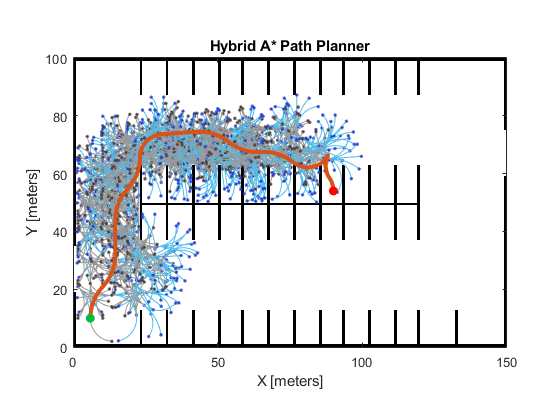

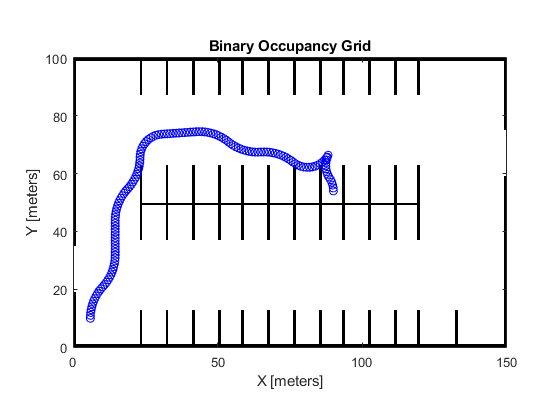

figure
show(map)
hold on
for i = 1: size(refpath.States,1)
    plot(refpath.States(i,1),refpath.States(i,2),'bo')
    drawnow
    hold on
end

*Copyright 2019 The MathWorks, Inc.*